Lab 0

Michael Laraia - 5124662

Jan 19, 2017

Question 1

ax=0:9

ax =      0     1     2     3     4     5     6     7     8     9


bx=[10.9 11.8 12.7 13.6 14.5 15.4 16.3 17.2 18.1 19.0]

bx =    10.9000   11.8000   12.7000   13.6000   14.5000   15.4000   16.3000   17.2000   18.1000   19.0000


cx=[-5 0 5 3 0 -3 -1 0 1 0]

cx =     -5     0     5     3     0    -3    -1     0     1     0



ay=1:150

ay =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


by=1:.75:150

by =     1.0000    1.7500    2.5000    3.2500    4.0000    4.7500    5.5000    6.2500    7.0000    7.7500    8.5000    9.2500   10.0000   10.7500   11.5000   12.2500   13.0000   13.7500   14.5000   15.2500   16.0000   16.7500   17.5000   18.2500   19.0000   19.7500   20.5000   21.2500   22.0000   22.7500   23.5000   24.2500   25.0000   25.7500   26.5000   27.2500   28.0000   28.7500   29.5000   30.2500   31.0000   31.7500   32.5000   33.2500   34.0000   34.7500   35.5000   36.2500   37.0000   37.7500



pix=ax.*3.1415

pix =          0    3.1415    6.2830    9.4245   12.5660   15.7075   18.8490   21.9905   25.1320   28.2735


abx=ax.*bx

abx =          0   11.8000   25.4000   40.8000   58.0000   77.0000   97.8000  120.4000  144.8000  171.0000


acx=ax+cx

acx =     -5     1     7     6     4     2     5     7     9     9


ababx=abx.*abx

ababx =    1.0e+04 *

         0    0.0139    0.0645    0.1665    0.3364    0.5929    0.9565    1.4496    2.0967    2.9241


byrt=sqrt(by)

byrt =     1.0000    1.3229    1.5811    1.8028    2.0000    2.1794    2.3452    2.5000    2.6458    2.7839    2.9155    3.0414    3.1623    3.2787    3.3912    3.5000    3.6056    3.7081    3.8079    3.9051    4.0000    4.0927    4.1833    4.2720    4.3589    4.4441    4.5277    4.6098    4.6904    4.7697    4.8477    4.9244    5.0000    5.0744    5.1478    5.2202    5.2915    5.3619    5.4314    5.5000    5.5678    5.6347    5.7009    5.7663    5.8310    5.8949    5.9582    6.0208    6.0828    6.1441


Question 2

M=csvread('lab0.csv',1)

M =         2500           3
        5000           3
        7500           1
       10000           3
       12500           7
       15000           5
       17500           4
       20000           1
       22500           4
       25000          11


h1=M(:,1)

h1 =         2500
        5000
        7500
       10000
       12500
       15000
       17500
       20000
       22500
       25000


h2=0.3048*h1

h2 =          762
        1524
        2286
        3048
        3810
        4572
        5334
        6096
        6858
        7620


r1=M(:,2)

r1 =      3
     3
     1
     3
     7
     5
     4
     1
     4
    11


r1err=sqrt(r1)

r1err =     1.7321
    1.7321
    1.0000
    1.7321
    2.6458
    2.2361
    2.0000
    1.0000
    2.0000
    3.3166



r2=1./r1

r2 =     0.3333
    0.3333
    1.0000
    0.3333
    0.1429
    0.2000
    0.2500
    1.0000
    0.2500
    0.0909


r2err=sqrt(r2)

r2err =     0.5774
    0.5774
    1.0000
    0.5774
    0.3780
    0.4472
    0.5000
    1.0000
    0.5000
    0.3015


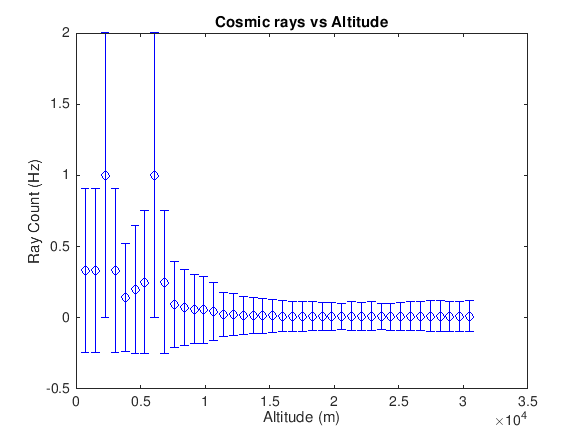


errorbar(h2, r2, r2err, 'bo')
xlabel('Altitude (m)')
ylabel('Ray Count (Hz)')
title('Cosmic rays vs Altitude')

Question 3

mm=[7 4 2; -1 5 5; 2 3 -9]

mm =      7     4     2
    -1     5     5
     2     3    -9


mminv=inv(mm)

mminv =     0.1357   -0.0950   -0.0226
   -0.0023    0.1516    0.0837
    0.0294    0.0294   -0.0882


Matrices are inverses if their product is the identity matrix, which is the case here

mminv*mm

ans =     1.0000   -0.0000   -0.0000
         0    1.0000    0.0000
   -0.0000    0.0000    1.0000


Question 4


$$\sigma_f^2 =\frac{\sigma_x^2 a^2 }{x^2 }+\frac{\sigma_y^2 4b^2 }{y^2 }$$



$$m_z =\frac{2\mathrm{qRB}}{c}$$



$$X^2 =\sum_{i} \frac{{\left(x_i -\overline{x} \right)}^2 }{\sigma_i^2 }$$
